%--------------------------
clear all;
cd('C:\Users\xy123\Matlab\Nlab_matlab/exp3_analysis/');

%-----------------------------------
% Acitivate at exp3_analysis
resultpath = "./results/";
ana_result = "analysis/";
Datapath = "./data/";

MatNames = {'cu0025', 'cu0129', 'pla0075', 'pla0225'};
MatNames1 = {'cu_0.025', 'cu_0.129', 'pla_0.075', 'pla_0.225'};
MatNames2 = {'cu-0.025', 'cu-0.129', 'pla-0.075', 'pla-0.225'};
HDRNames3 = [1,2,3,4,5,6,7,8,9,10,11,12,13,14,15,16,17,18,19,20,21,22,23,24,25,26,27,28,29,30];
HDRlNames2 = [19, 39, 78, 80, 102, 125, 152, 203, 226, 227, 230, 232, 243, 278, 281];
HDRNames = [5,19,34,39,42,43,78,80,102,105,125,152,164,183,198,201,202,203,209,222,226,227,230,232,243,259,272,278,281,282];
ShapeNames = {'sphere','bunny','dragon','boardA','boardB','boardC'};

% load data
load(strcat(Datapath,'Exp1_data.mat'));
load(strcat(Datapath,'Exp2_data.mat'));
load(strcat(Datapath,'Exp3_data.mat'));
load(strcat(Datapath,'Inoue_data.mat'));

%-----------------------------------
% Exp3 Material Shape
%-----------------------------------
for matnum = 1:size(Exp3HMSNorm,2)
    figure;
    hold on;
    for shapenum = 1:size(Exp3HMSNorm,3)
        subplot(2, 3, shapenum);
        bar_width = 0.35;
        x = 1:length(HDRNames);
    
        bar(x + bar_width/2, Exp3HMSNorm(:,matnum, shapenum), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
        errorbar(x + bar_width/2, Exp3HMSNorm(:,matnum,shapenum), error_Exp3HMS(:,matnum,shapenum), 'k', 'linestyle', 'none');
    
        ylim([-1.2 1.2]);
        set(gca, 'XTick', 1:length(HDRNames3));
        set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
        xlabel('HDR', 'FontSize', 16); 
        ylabel('Average z-score', 'FontSize', 16);
        title(['compare of ' MatNames2{matnum} '&' ShapeNames{shapenum}], 'FontSize', 16);
        %legend([b2,b3],{'2D','3D'}, 'Location', 'best');
    end
    plotname = strcat(ana_result, '/Exp3_MS_', MatNames2{matnum},'.jpg');
    saveas(gcf, plotname);
    hold off;
end

%-----------------------------------
% Exp3 Material
%-----------------------------------
figure;
hold on;
for matnum = 1:4
    subplot(2, 2, matnum);
    bar_width = 0.35;
    x = 1:length(HDRNames);

    bar(x + bar_width/2, Exp3HMNorm(:,matnum), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    errorbar(x + bar_width/2, Exp3HMNorm(:,matnum), error_Exp3HMSNorm(:,matnum), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(HDRNames3));
    set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Average z-score', 'FontSize', 16);
    title(['compare of ' MatNames2{row}], 'FontSize', 16);
    %legend([b2,b3],{'2D','3D'}, 'Location', 'best');
end
plotname = strcat(ana_result, '/Exp3_Material', '.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% Exp3 Shape
%-----------------------------------
figure;
hold on;
for shapenum = 1:size(Exp3HSNorm,2)
    subplot(2,3,shapenum);
    bar_width = 0.35;
    x = 1:length(HDRNames);

    bar(x + bar_width/2, Exp3HSNorm(shapenum, :), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    errorbar(x + bar_width/2, Exp3HSNorm(shapenum, :), error_Exp3HSNorm(shapenum,:), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(HDRNames3));
    set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Average z-score', 'FontSize', 16);
    title(['compare of ' ShapeNames{shapenum}], 'FontSize', 16);
    %legend([b2,b3],{'2D','3D'}, 'Location', 'best');

end
plotname = strcat(ana_result, '/Exp3_', 'Shape','.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% Exp3 HDR
%-----------------------------------
figure;
hold on;
bar_width = 0.35;
x = 1:length(HDRNames);
avb = bar(x + bar_width/2, Exp3HNorm, bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
avh = errorbar(x + bar_width/2, Exp3HNorm, error_Exp3HNorm, 'k', 'linestyle', 'none');
ylim([-1.2 1.2]);
set(gca, 'XTick', 1:length(HDRNames3));
set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
xlabel('HDR', 'FontSize', 16); 
ylabel('Normalized z-score', 'FontSize', 16);
title('HDR', 'FontSize', 16);
plotname = strcat(ana_result, '/Exp3_HDR.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% Inoue material
%-----------------------------------
figure;
hold on;
for matnum = 1:size(InoueHMNorm,2)
    subplot(2,2,matnum);
    bar_width = 0.35;
    x = 1:length(colNames);

    b3 = bar(x + bar_width/2, InoueMHNorm(:,matnum), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    %h3 = errorbar(x + bar_width/2, InoueMHNorm(:,row), error_exp3(row,:), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(colNames));
    set(gca, 'XTickLabel', colNames, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Average z-score', 'FontSize', 16);
    title(['compare of ' InoueMatname{matnum}], 'FontSize', 16);
end
plotname = strcat(ana_result, '/Old_Material','.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% Inoue Shape
%-----------------------------------
figure;
hold on;
for shapenum = 1:size(InoueHSNorm,2)
    bar_width = 0.35;
    x = 1:length(colNames);

    b3 = bar(x + bar_width/2, InoueSHNorm(:,shapenum), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    %h3 = errorbar(x + bar_width/2, InoueSHNorm(:,row), error_exp3(row,:), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(colNames));
    set(gca, 'XTickLabel', colNames, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Normalized z-score', 'FontSize', 16);
    title(['compare of ' InoueShapeName{shapenum}], 'FontSize', 16);
end
plotname = strcat(ana_result, '/Old_Shape', '.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% Inoue material shape
%-----------------------------------
for matnum = 1:size(InoueHMSNorm,2)
    figure;
    hold on;
    for shapenum = 1:size(InoueHMSNorm,3)
        subplot(2,3,shapenum);
        bar_width = 0.35;
        x = 1:length(HDRNames);
    
        bar(x + bar_width/2, InoueHMSNorm(:,matnum, shapenum), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
        %errorbar(x + bar_width/2, InoueMHSNorm(:,matnum, shapenum), error_Exp3MHS(matnum,:,shapenum), 'k', 'linestyle', 'none');
    
        ylim([-1.2 1.2]);
        set(gca, 'XTick', 1:length(HDRNames3));
        set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
        xlabel('HDR', 'FontSize', 16); 
        ylabel('Average z-score', 'FontSize', 16);
        title(['compare of ' InoueMatname{matnum} '&' InoueShapeName{row}], 'FontSize', 16);
        %legend([b2,b3],{'2D','3D'}, 'Location', 'best');
    end
    plotname = strcat(ana_result, '/Old_MS_', InoueMatname{matnum},'.jpg');
    saveas(gcf, plotname);
    hold off;
end

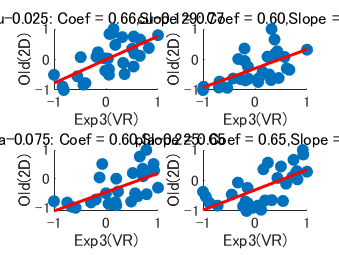

%-----------------------------------
% Exp3 vs Old HDR,Material coef
%-----------------------------------
figure;
for matnum = 1:4
    x = Exp3HMNorm(:,matnum);
    y = InoueHMNorm(:,matnum);
    r = corrcoef(x,y);
    r_value = r(1,2);
    p = polyfit(x,y,1);
    p_fit = polyval(p,x);

    subplot(2, 2, matnum);
    scatter(x,y,'filled');
    hold on;
    plot(x,p_fit,'r-','LineWidth',1.5);
    hold off;

    xlabel('Exp3(VR)');
    ylabel('Old(2D)');
    title(sprintf('%s: Coef = %.2f,Slope = %.2f', string(MatNames2(matnum)),r_value,p(1)));
end
plotname = strcat(ana_result, '/Exp3vsOld_Mat_Coef.jpg');
saveas(gcf, plotname);
hold off;

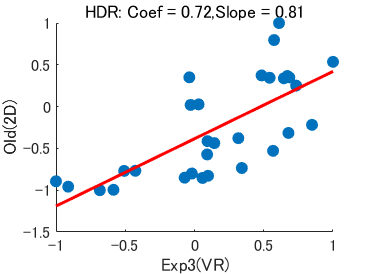

%-----------------------------------
% Exp3 vs Old HDR coef
%-----------------------------------
figure;

x = Exp3HNorm(:);
y = InoueHNorm(:);
r = corrcoef(x,y);
r_value = r(1,2);
p = polyfit(x,y,1);
p_fit = polyval(p,x);

scatter(x,y,'filled');
hold on;
plot(x,p_fit,'r-','LineWidth',1.5);
hold off;

xlabel('Exp3(VR)');
ylabel('Old(2D)');
title(sprintf('HDR: Coef = %.2f,Slope = %.2f', r_value,p(1)));

plotname = strcat(ana_result, '/Exp3vsOld_HDR_Coef.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% Exp3 vs Inoue graph
%-----------------------------------
figure;
hold on;
bar_width = 0.35;
x = 1:length(HDRNames);
avb1 = bar(x + bar_width/2, AvExp3zscore, bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
avh1 = errorbar(x + bar_width/2, AvExp3zscore, error_av_O, 'k', 'linestyle', 'none');
avb2 = bar(x - bar_width/2, InoueHNorm_b, bar_width, 'FaceColor', 'r', 'DisplayName', '3D'); 
avh2 = errorbar(x - bar_width/2, InoueHNorm_b, error_av_I, 'k', 'linestyle', 'none');
ylim([-1.2 1.2]);
set(gca, 'XTick', 1:length(HDRNames3));
set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
xlabel('HDR', 'FontSize', 16); 
ylabel('Average z-score', 'FontSize', 16);
title('compare of Average', 'FontSize', 16);
legend([avb1, avb2], {'VR', '2D'}, 'Location', 'best');
plotname = strcat(ana_result, '/O_Average_hikaku.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% exp2 VS VR
%-----------------------------------
%bar graph
for row = 1:4
    figure;
    hold on;
    bar_width = 0.35;
    x = 1:length(HDRNames);

    % exp2のプロット
    b2 = bar(x - bar_width/2, Exp2HMNorm30(row, :), bar_width, 'FaceColor', 'r', 'DisplayName', '2D'); 
    h2 = errorbar(x - bar_width/2, Exp2HMNorm30(row, :), error_Exp2HM(row,:), 'k', 'linestyle', 'none');

    % exp3のプロット
    b3 = bar(x + bar_width/2, Exp3HMSNorm(row, :), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    h3 = errorbar(x + bar_width/2, Exp3HMSNorm(row, :), error_Exp3HMS(row,:), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(HDRNames));
    set(gca, 'XTickLabel', HDRNames, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Average z-score', 'FontSize', 16);
    title(['compare of ' MatNames2{row}], 'FontSize', 16);
    legend([b2,b3],{'2D','3D'}, 'Location', 'best');

    plotname = strcat(ana_result, '/', MatNames2{row}, '.jpg');
    saveas(gcf, plotname);
    hold off;
end

%correlation_coefficients
correlation_coefficients = zeros(1, 4);
for row = 1:4
    data_exp2 = Exp2HMNorm30(row, :);
    data_exp3 = Exp3HMSNorm(row, :);
    corr_matrix = corrcoef(data_exp2, data_exp3);
    correlation_coefficients(row) = corr_matrix(1, 2);
end

disp(correlation_coefficients);